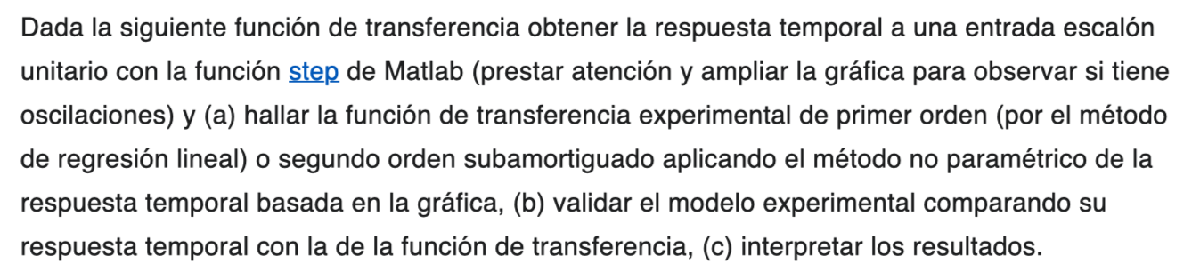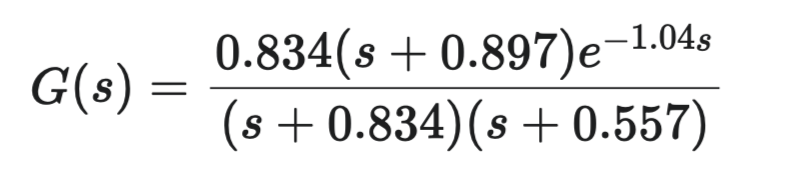

G = zpk([-0.897],[-0.834 -0.557],0.834,'InputDelay',1.04)

G =
 
                0.834 (s+0.897)
  exp(-1*s) * -------------------
              (s+0.834) (s+0.557)
 
Continuous-time zero/pole/gain model.



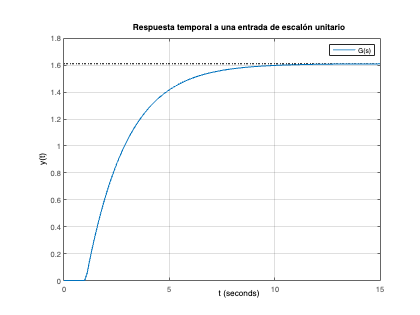

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 15;
figure(1)
clf
step(G,tiempofinal)
grid on
legend({'G(s)'})
title("Respuesta temporal a una entrada de escalón unitario")
xlabel('t')
ylabel('y(t)')


[y,t] = step(G,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1) %valor de k según la fórmula

k = 1.6096

k = 1.61;

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1); %valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',abs(tau))%función de transferencia resultante

tfEstimada =
 
                    1.61
  exp(-1.31*s) * -----------
                 1.732 s + 1
 
Continuous-time transfer function.



*b) Validación*

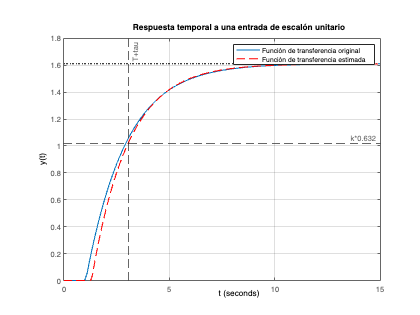

clf
figure(1)
step(G,tiempofinal)
grid on
hold on
step(tfEstimada, 'r--')
xline(T+tau, '--',{'T+tau'})
yline(k*0.632,'--', {'k*0.632'})
legend({'Función de transferencia original','Función de transferencia estimada'})
title("Respuesta temporal a una entrada de escalón unitario")
xlabel('t')
ylabel('y(t)')

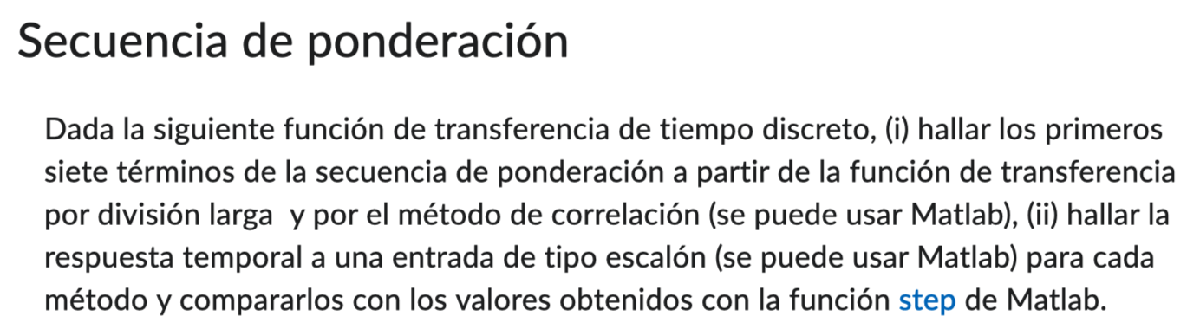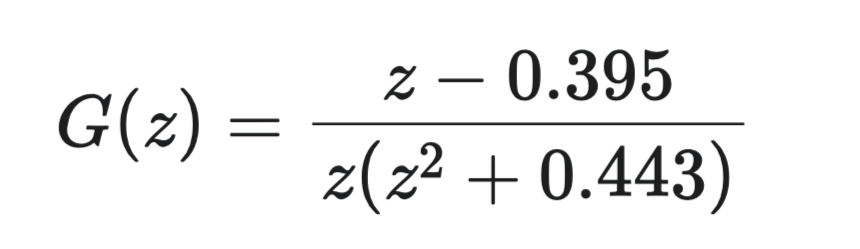

num = [1 -0.395];
den = [1 0 0.443 0];
G = tf(num,den,1)

G =
 
    z - 0.395
  -------------
  z^3 + 0.443 z
 
Sample time: 1 seconds
Discrete-time transfer function.



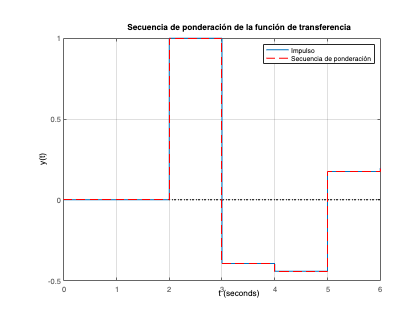

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(G,0:1:L-1); %impulso
hold on
stairs(0:1:L-1, Secuencia,'r', 'LineStyle','--')
grid on
legend({'Impulso','Secuencia de ponderación'})
title("Secuencia de ponderación de la función de transferencia")
xlabel('t')
ylabel('y(t)')

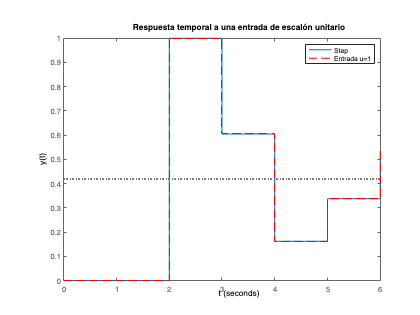


clf
step(G,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r', 'LineStyle','--')
legend({'Step','Entrada u=1'})
title("Respuesta temporal a una entrada de escalón unitario")
xlabel('t')
ylabel('y(t)')